# Gradient Nonlinearity Demo

This is a Matlab live script, you can run the whole thing at once, or run each cell like a normal script cell.

Code Creation: Michael Loecher

DBE@STANFORD.EDU (April 2020 for Rad229)

## Characterizing Nonlinear Gradients 

Nonlinear gradients can be represented with spherical harmonics:

[https://onlinelibrary.wiley.com/doi/full/10.1002/mrm.20122](https://onlinelibrary.wiley.com/doi/full/10.1002/mrm.20122)

Where we calculate the true gradient field following Eq 4.  The alpha and beta terms from that equation are provided by the magnet vendor, which they have **characterized for a given gradient coil construction**.  These characterizations are proprietary, so for this code example we generated our own (in a similar range to real values).

load('synth_coeff.mat');

An example of what these coefficients look like for the alpha term of the Gx field:

disp('Alpha_x ='); disp(Alpha_x);

Alpha_x =
            0            0            0            0            0            0            0            0            0            0            0            0
            0            0            0            0            0            0            0            0            0            0            0            0
            0            0            0            0            0            0            0            0            0            0            0            0
            0    -0.062643            0   -0.0052672            0            0            0            0            0            0            0            0
            0            0            0            0            0            0            0            0            0            0            0            0
            0     -0.07361            0   -0.0026678            0   -0.0013907            0            0            0            0            0            0
            0            0            0         

## Calculating the Fields

We will calculate the gradient field from the **spherical harmonics**. *(NOTE: This cell can take 10-20 seconds to run, you can lower N in this code block to make it go faster)*

fov_r = 500;  % Look at 500mm FOV
N = 64;  % Number of points to sample

range_r = linspace(-fov_r/2, fov_r/2, N);

% Locations to calculate gradient at (in mm)
[Rx, Ry, Rz] = ndgrid(range_r, range_r, range_r);

We then calculate the field at each of these locations.  This code is fairly complicated, so it will be left unexplained, but you can look at the previously mentioned paper and the Wikipedia page on **spherical harmonics** to help understand. 

x = Rx(:).';
y = Ry(:).';
z = Rz(:).';

% These calculate the spherical harmonics
bx = calc_harmonics(Alpha_x, Beta_x, x, y, z, R0);
by = calc_harmonics(Alpha_y, Beta_y, x, y, z, R0);
bz = calc_harmonics(Alpha_z, Beta_z, x, y, z, R0);

Bx = reshape(bx, size(Rx));
By = reshape(by, size(Ry));
Bz = reshape(bz, size(Rz));

% Apply a scale factor (vendor characterized/supplied)
Dx = Bx * R0;
Dy = By * R0;
Dz = Bz * R0;

These fields (Dx, Dy, Dz) contain the error **displacement field in mm**.  i.e. for each location we calculate where the voxel has distorted to in the image.  

## Visualizing the Fields

We now visualize the distortion in the z direction (Dz) in a sagittal plane.

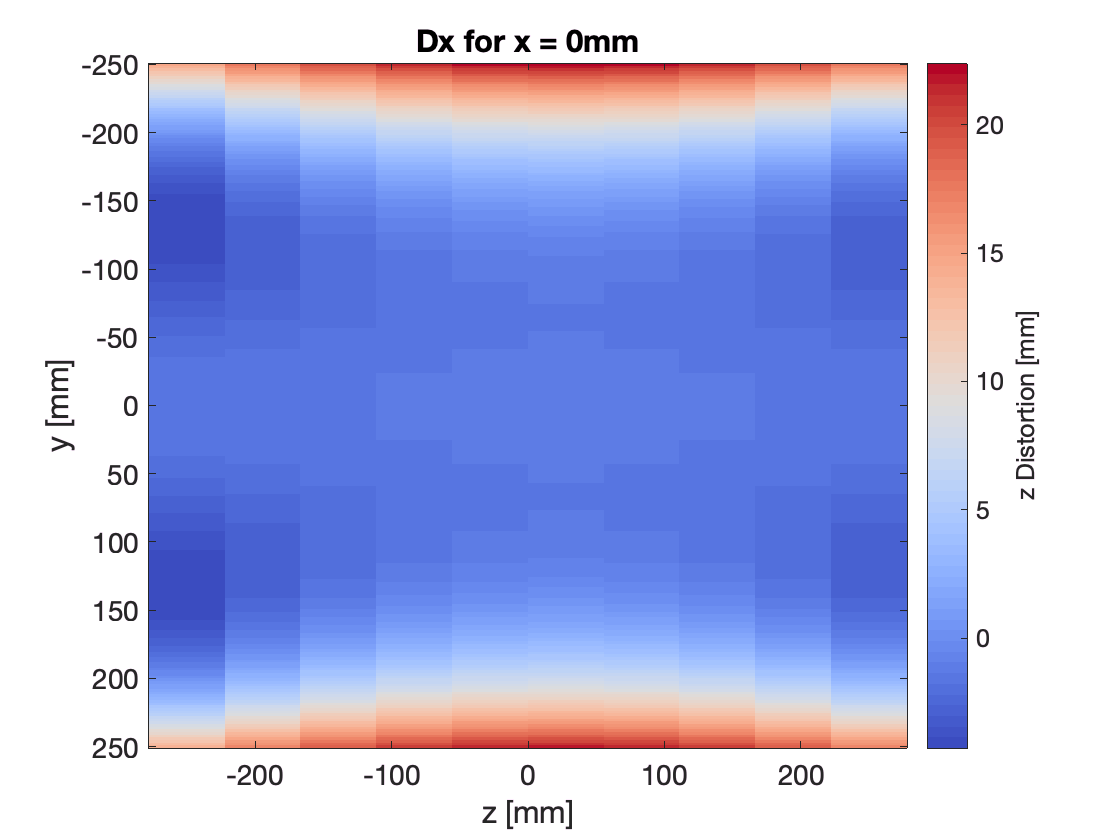

figure()
imagesc(range_r, range_r, squeeze(Dx(N/2,:,:)));
title('Dx for x = 0mm');
xlabel('z [mm]');
ylabel('y [mm]');
colormap(coolwarm);
c = colorbar;
c.Label.String = 'z Distortion [mm]';
axis image;
set(gca,'FontSize',14)

You will notice that the displacements shown here are huge (**5 cm error at the edges**).  This is mostly because we are looking at a FOV that is much bigger than anything we would acquire clinically, but even with normal clinical FOVs, the uncorrected distortion can be significant.

We can also calculate what the gradient field looks like by simply adding the distortion to our initial positions (positions are directly related to the gradient).  Then we take line profiles through the volume we calculated.

% These are the absolute distorted positions
Rx_w = Rx + Dx;

Array dimensions must match for binary array op.

Ry_w = Ry + Dy;
Rz_w = Rz + Dz;

% Scale these values to create arbitrary magnetic field units, we cannot
% know the 'real' field, i.e. milliTesla because the scaling could be 
% anything and would be sequence specific
Gx = Rx/fov_r;  Gy = Ry/fov_r;  Gz = Rz/fov_r;
Gx_w = Rx_w/fov_r;  Gy_w = Ry_w/fov_r;  Gz_w = Rz_w/fov_r;

% Plot
figure()
plot(range_r, squeeze(Gz(N/2, N/2, :)), 'LineWidth', 2);
hold on;
plot(range_r, squeeze(Gz_w(N/2, N/2, :)), 'LineWidth', 2);
xlabel('z [mm]')
ylabel('Bz [AU]')
legend('Ideal Gz', 'Actual Gz', 'Location', 'northwest');
set(gca,'FontSize',14)

Where we see the **classic nonlinear gradient behavior**.

While we expect Gz to be consistent for all x and y positions, due to nonlinearities it is not (as well as for Gx and Gy).

% Plot
figure()
plot(range_r, squeeze(Gz(N/2, N/2, :)), 'LineWidth', 2);
hold on;
plot(range_r, squeeze(Gz_w(N/2, N/2, :)), 'LineWidth', 2);
plot(range_r, squeeze(Gz_w(N/4, N/4, :)), 'LineWidth', 2);
xlabel('z [mm]')
ylabel('Bz [AU]')
legend('Ideal Gz', ...
       sprintf('Actual Gz at x=%.1f y=%.1f', 0.0, 0.0), ...
       sprintf('Actual Gz at x=%.1f y=%.1f', -fov_r/4.0, -fov_r/4.0), ...
       'Location', 'northwest');
set(gca,'FontSize',14)

## Digital Phantom

We will generate a phantom with grid lines to help visualize distortion:

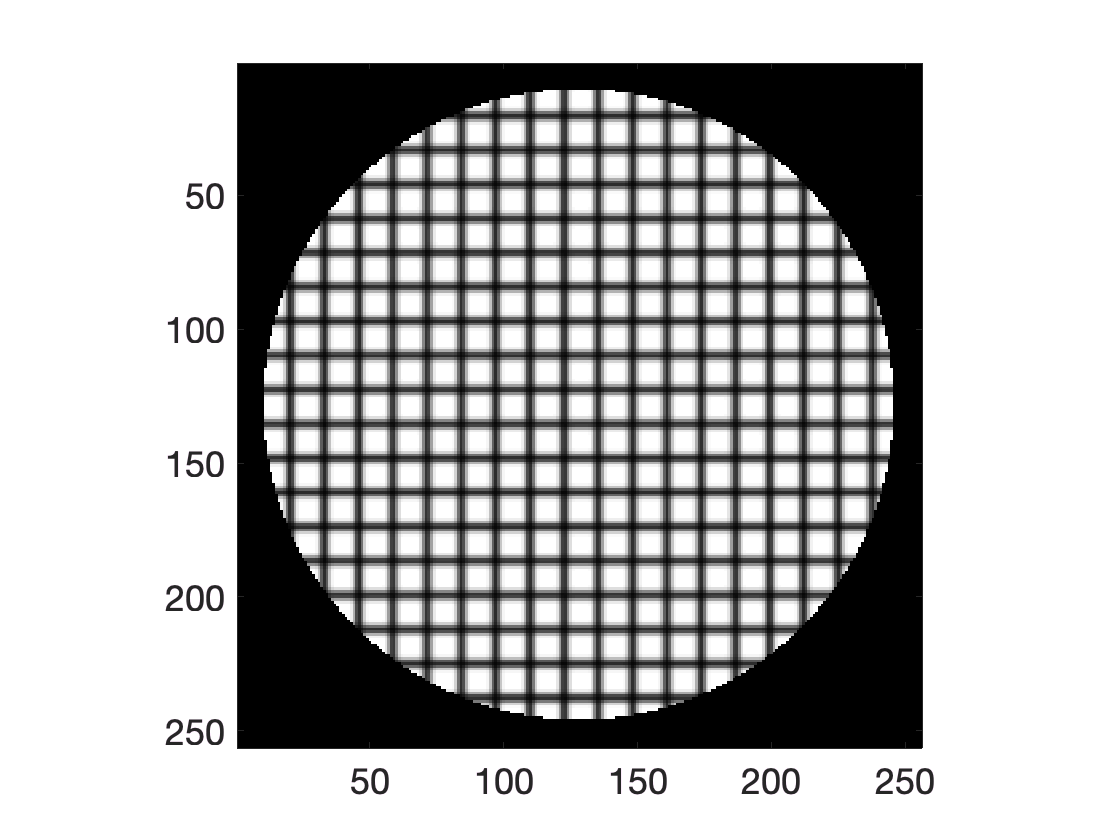

imsize = 256; % In-plane number of voxels

im0 = grid_phantom(imsize);

figure();
imagesc(im0);
colormap(gray);
axis image;

We will make it 3D to visualize the through plane components later.  Only 10 slices for compute speed.

Nz = 10;
im0 = repmat(im0, [1,1,Nz]);

fprintf('im0 size = %d %d %d', size(im0));

im0 size = 256 256 10

## Distort Phantom

We can distort the phantom by first recomputing the distortion as we did before. We will need a coordinate transform matrix to bring us from Matlab coordinates [x,y,z = 1,2,3...255,256] to scanner coordinates [x,y,z = -FOV/2 to FOV/2 mm].

% Coordinates in Matlab 1-256 notation
[Vx, Vy, Vz] = ndgrid(1:size(im0,1), 1:size(im0,2), 1:size(im0,3));

% This maps the Matlab coordinates to the real world RAS coordinate 
% system. So 1,3,2 is R (right), S (superior), A (anterior). 
% So this will be a coronal slice
coord_dirs = [1,3,2];

% This is the resolution in mm, in each Matlab dimension. We do 
% unrealistically big slices to visualize more FOV
res = [1.5, 1.5, 20.0];

% Get the transform matrix
coords = get_coords(coord_dirs, res, im0);

% Convert the Matlab coords to scanner coords
[Sx, Sy, Sz] = transform_coords(Vx, Vy, Vz, coords);

disp('coords ='); disp(coords);

coords =
          1.5            0            0       -193.5
            0            0           20         -120
            0          1.5            0       -193.5
            0            0            0            1



We now get the distortion values for each of these voxel scanner positions. *(This can take a couple seconds).*

% Get the distortion (Same code as above, just in a function)
[Dx, Dy, Dz] = get_distortion(Sx, Sy, Sz, Alpha_x, Alpha_y, Alpha_z, ...
                                         Beta_x, Beta_y, Beta_z, R0);

% Get the distorted coordinates
Sx_d = Sx + Dx;
Sy_d = Sy + Dy;
Sz_d = Sz + Dz;

To 'apply' the distortion we just interpolate the positions using a built in Matlab function called scatteredInterpolant.

% We first convert back to the matlab coordinate system
[Vx_d, Vy_d, Vz_d] = transform_coords(Sx_d, Sy_d, Sz_d, inv(coords));

% Then we interopolate each voxel in our image to their distorted position
F = scatteredInterpolant(Vx_d(:), Vy_d(:), Vz_d(:), im0(:));
im_d = F(Vx, Vy, Vz);

Display distorted image

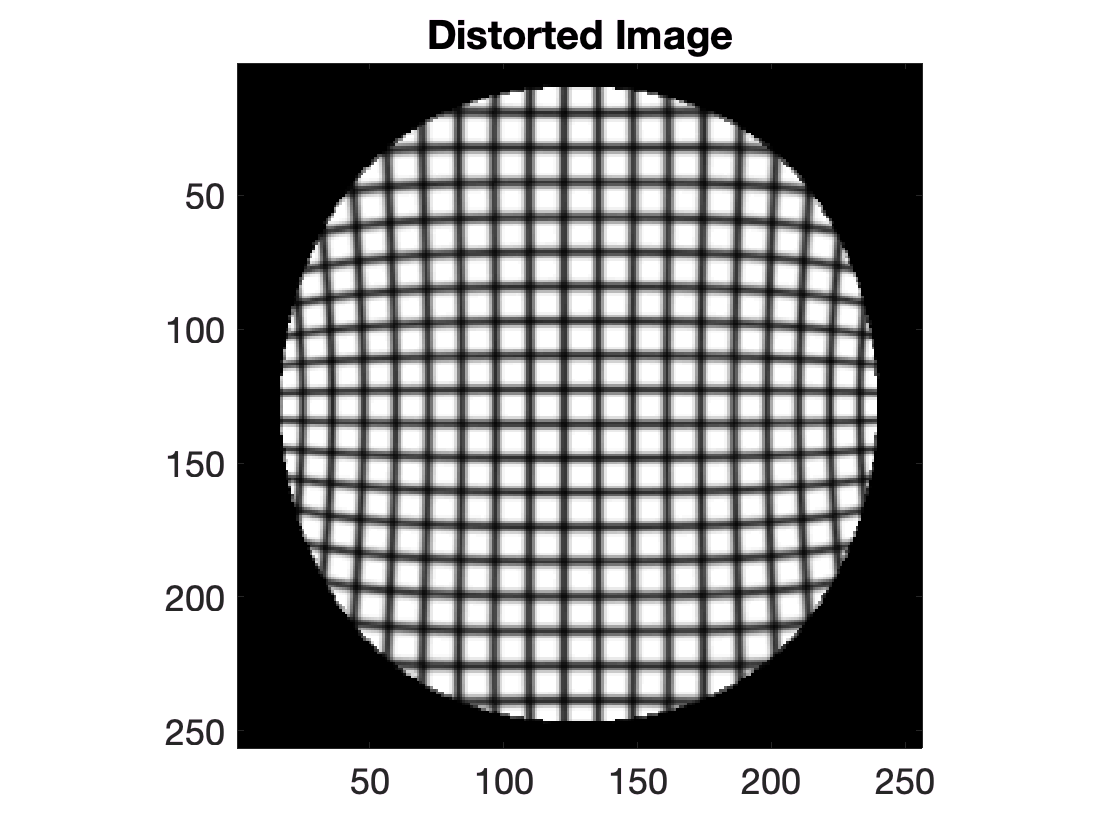

figure();
imagesc(im_d(:,:,Nz/2));
colormap(gray);
axis image;
title('Distorted Image')